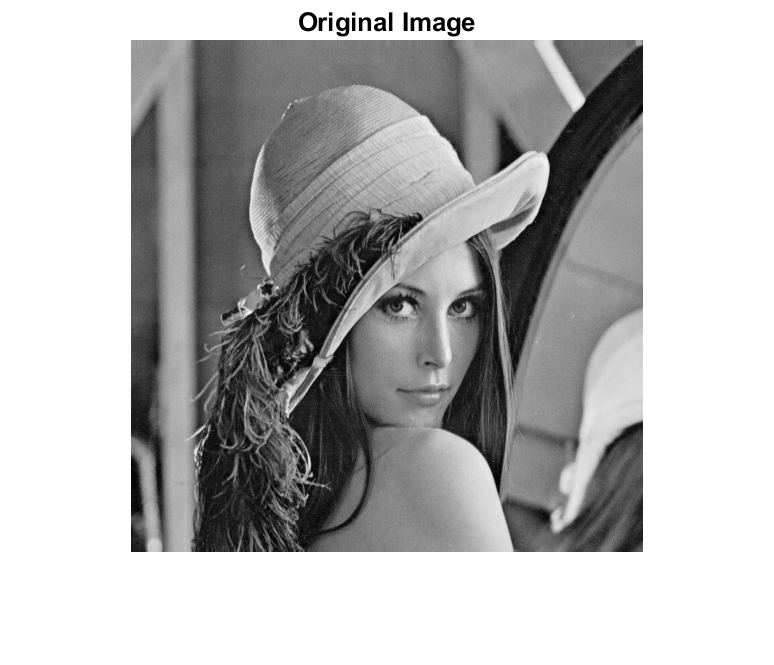

% example of dct denoising
clear
close all

% load the image and rescale it in [0,1]
% img = im2double(imread('cameraman.tif'));
% img = im2double(imread('../BM3D_images/barbara.png'));
img = im2double(imread('C:/Users/simo9/Desktop/MMMIP/MMIP_lez4/MMIP_lez4/BM3D_images/Lena512.png'));

% set the noise level
sigma_noise = 20/255;

% set the patch size
p = 8;

% corrupt the image with additive white gaussian noise
noisy_img = img + random('normal', 0, sigma_noise, size(img));

% compute the PSNR of the noisy input
psnr_noisy = 10 * log10(size(img, 1) * size(img,2)/sum((img - noisy_img).^2, 'all'));

figure(1), imshow(img,[]), title('Original Image')

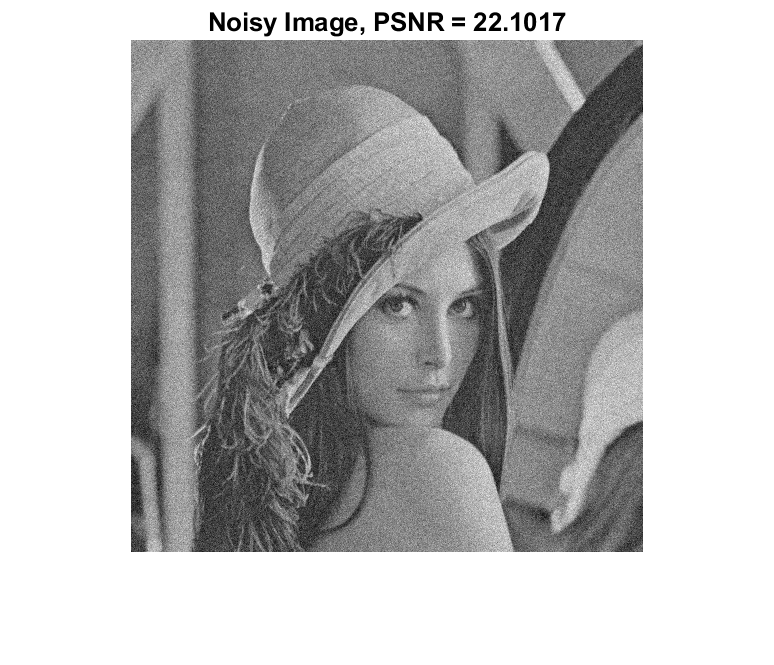

figure(2), imshow(noisy_img,[]), title(['Noisy Image, PSNR = ',num2str(psnr_noisy)])

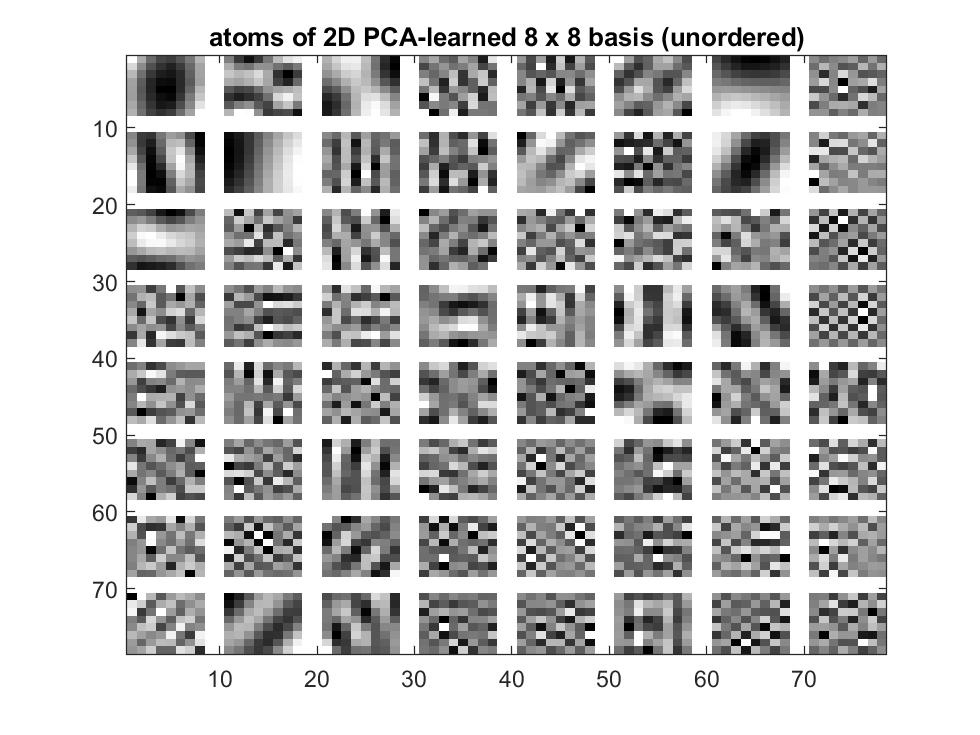


% Stack all image patches in a large matrix P. Each patch goes in a column of P
P = zeros(p*p, size(img,1)*size(img,2)/p/p);
% populate the large patch matrix P
for ii=1:p:size(img, 1)
    for jj=1:p:size(img,2)
        patch = img(ii:ii+p-1,jj:jj+p-1);
        patch = reshape(patch, 1,[]);
        P(:,ceil(jj/p) + (ii-1)/p*size(img,2)/p) = patch-avg;
    end
end
% Preprocessing: compute the average_patch to be subtracted 
avg_patch = zeros(p*p, 1);
for ii=1:p*p
    avg_patch(ii, 1) = mean(P(ii,:));
end
% zero-center the matrix before computing the basis
Pc = P - avg_patch; 

% compute the PCA transformation via SVD from Pc
[U, Sigma, ~] = svd(Pc*Pc');

% select the number of PC to preserve (set a percentage of explained variance)
cumulative_sum = 0;
explained_variance = 0.95;
k = 1;
prec_explained_variances = diag(Sigma)/sum(diag(Sigma));
while cumulative_sum<explained_variance
    cumulative_sum = cumulative_sum + prec_explained_variances(k);
    k = k+1;
end

% define the PCA projection operator over the firqst k components
Uk = U(:, 1:k);
explained_variances = prec_explained_variances(1:k)*sum(diag(Sigma));

% display the learned PCA basis 
figure(), show_dictionary(U);
title(['atoms of 2D PCA-learned ', num2str(p) ,' x ', num2str(p) , ' basis (unordered)'])

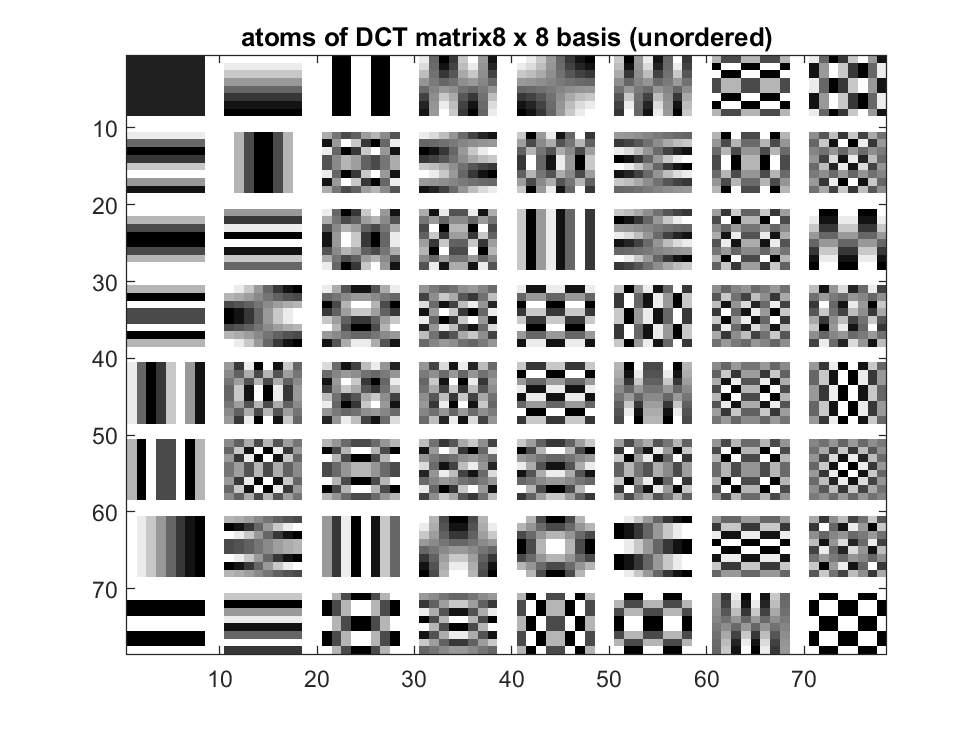


%comparison with dct basis
DCT = zeros(size(U));
for i = 1:size(U, 1)
    DCT(i,i)=1;
    DCT(:,i) =reshape(idct2(reshape(DCT(:,i), [p,p])')', [1,p*p]);
end

figure(), show_dictionary(DCT);
title(['atoms of DCT matrix', num2str(p) ,' x ', num2str(p) , ' basis (unordered)'])

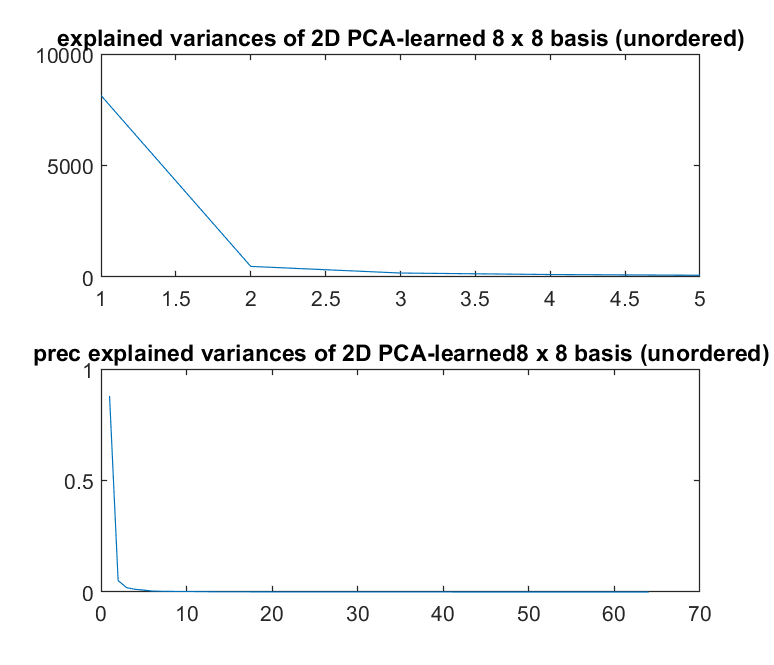



figure(2)
subplot(2,1,1), plot(explained_variances);
title(['explained variances of 2D PCA-learned ', num2str(p) ,' x ', num2str(p) , ' basis (unordered)'])
subplot(2,1,2), plot(prec_explained_variances);
title(['prec explained variances of 2D PCA-learned', num2str(p) ,' x ', num2str(p) , ' basis (unordered)'])

do_ht = 1;

% initialize the output image
img_hat = zeros(size(noisy_img));

% initialize the weight matrix
weights = zeros(size(noisy_img));

% set the threshold for the Hart Thresholding
tau = 3 * sigma_noise; % Donoho says: sigma * sqrt(2*log(p^2))
 
% define the step (=p for non overlapping patches)
STEP = 1; 

tic
% operates patch-wise
for ii = 1 : STEP : (size(noisy_img,1)-p+1)
    for jj=1 : STEP : (size(noisy_img,2)-p+1) 
        % Preprocessing: remember to subtract the avg_patch (preprocessing used for PCA)
        s = noisy_img(ii:ii+p-1, jj:jj+p-1) - reshape(avg_patch, [p,p]);
        % extract the patch with the top left cornner at pixel (ii,jj)
        
        % Pca denoising
        if do_ht
            
            % Analysis: compute the representation w.r.t. the PCA basis
            x = reshape(s, [1,p*p]) * U;
            
            
            % perform Hard Thresholding (there is no DC component in PCA!!)
            x_hat = (abs(x)>tau).*x;
            
            % Synthesis: invert the thresholded coefficients
            s_hat = x_hat / U;
            
        else
            % compute the projection over the subspace spanned by the first k PC 
            x = zeros([1,p*p]);
            x(1,1:k) = reshape(s, [1,p*p]) * Uk;
            
            % invert the projection back to the entire space
            s_hat = x / U;
        end
        
        % Invert the preprocessing: bring avg_patch back. 
        s_hat = s_hat + reshape(avg_patch, [1,p*p]);
        %Aggregation
        % compute the weight for the reconstructed patch
        w = 1;
        
        % put the reconstructed patch in the estimated image using the computed weight
        % upate img_hat
        img_hat(ii:ii+p-1, jj:jj+p-1) = img_hat(ii:ii+p-1, jj:jj+p-1) + reshape(s_hat, [p,p]);
        
        % store the weight of the current patch in the weight matrix
        % update weights
        weights(ii:ii+p-1,jj:jj+p-1) = weights(ii:ii+p-1,jj:jj+p-1) + ones([p,p])*w;
    end
end
toc

Elapsed time is 47.089147 seconds.



% normalize the estimated image with the computed weights
img_hat =  img_hat./weights;

% compute the psnr of the estimated image
psnr_hat = 10 * log10(size(img_hat, 1) * size(img_hat,2)/sum((img_hat - img).^2, 'all'));
str = sprintf('PSNR : %2.3f', psnr_hat);
disp(['\n', str, '\n'])

\nPSNR : 32.085\n


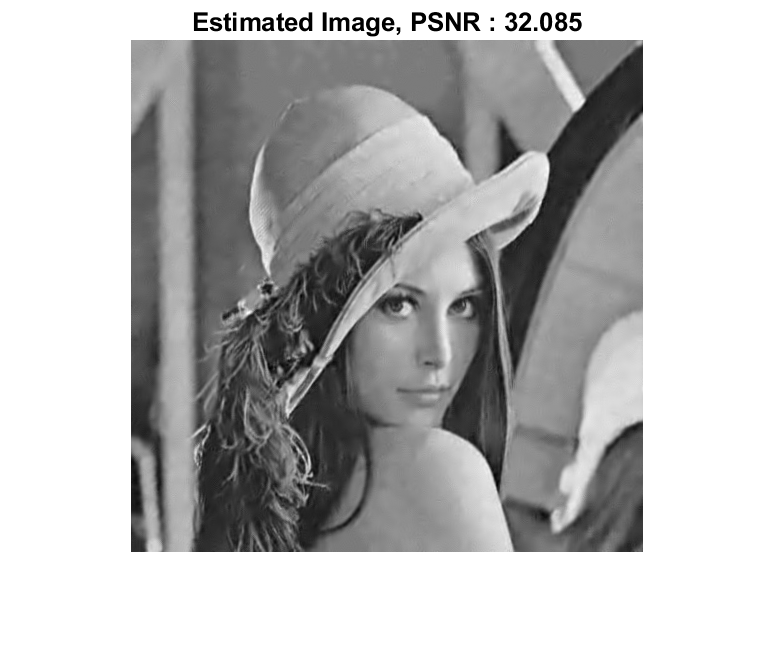

figure(3), imshow(img_hat,[]), title(['Estimated Image, ', str])

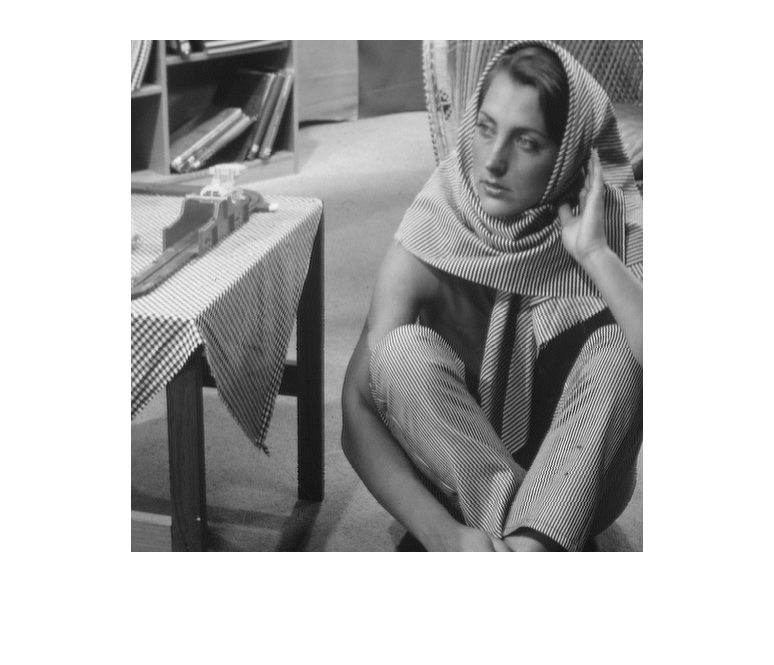

img = im2double(imread('C:\Users\simo9\Desktop\MMMIP\MMIP_lez4\MMIP_lez4\BM3D_images\barbara.png'));
imshow(img)

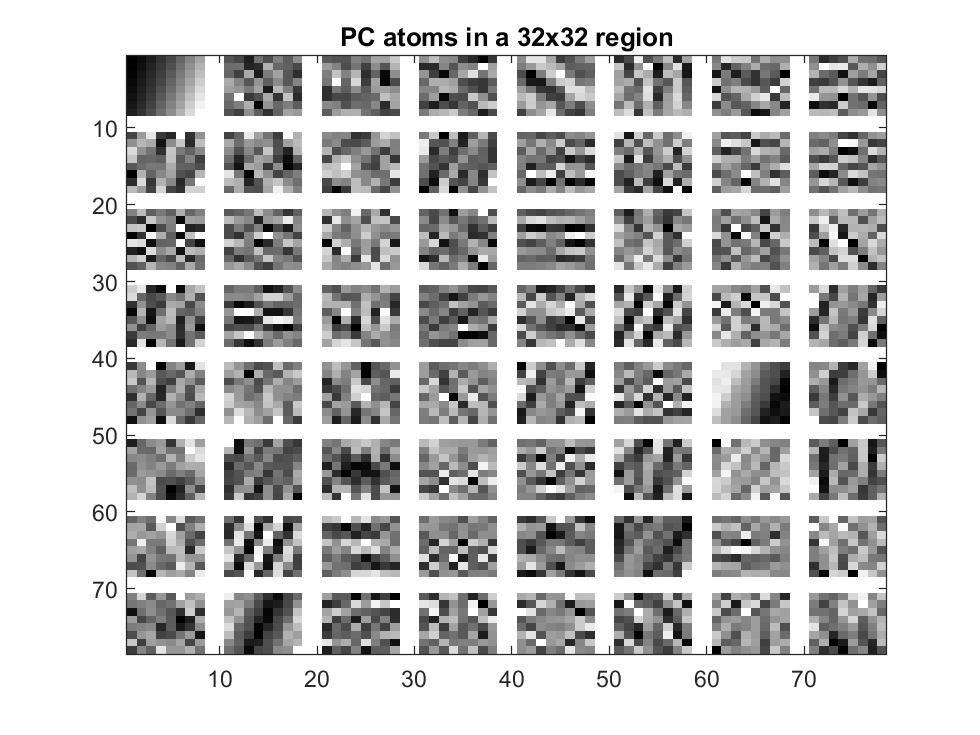

[U_region, Sigma_region, V_region, avg] = pca_region(img, 376,450,32);
figure(), show_dictionary(U_region);
title(['PC atoms in a 32x32 region'])

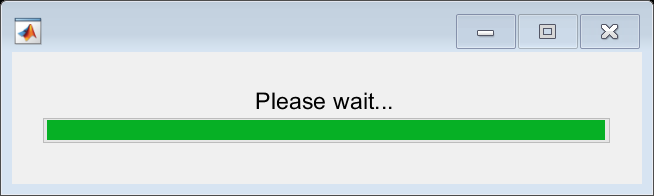

%% Denoising by local pca basis ht
tile_dim = 32;
%STEP = 32; %% NON Overlapping tiles
STEP = 8; %% Overlapping tiles, my pc is a poor guy and this is the smallest step i can try
num_tiles = size(img, 1) * size(img, 2) / tile_dim /tile_dim;
U = zeros([p*p, p*p, num_tiles]);
Sigma = zeros([p*p, p*p, num_tiles]);
V = zeros([p*p, p*p, num_tiles]);
zz = 1;
avg_patches = zeros(p*p,num_tiles);
img_hat = zeros(size(img));
weights = zeros(size(img));
f = waitbar(0,'Please wait...');

tic
for ii=1:STEP:size(img,1)-tile_dim+1
    for jj=1:STEP:size(img,2)-tile_dim+1
        %ii e jj servono a indicare langolo in alto a sinistra
        [U(:,:,zz), Sigma(:,:,zz), V(:,:,zz), avg_patches(:,zz)] = pca_region(img, ii, jj, tile_dim);
        tile = img(ii:ii+tile_dim-1, jj:jj+tile_dim-1);
        

        for iip=1:tile_dim-p+1
            for jjp=1:tile_dim-p+1
                patch = tile(iip:iip+p-1, jjp:jjp+p-1);
                patch = patch(:) - avg_patches(:,zz);
                x = patch' * U(:,:,zz);
                x_hat = (abs(x)>tau).*x;
                s_hat = x_hat / U(:,:,zz);
                s_hat = s_hat' + avg_patches(:,zz);
                %correspondent indexes in the original image
                r = ii+iip-1;
                c = jj+jjp-1;
                img_hat(r:r+p-1,c:c+p-1) = img_hat(r:r+p-1,c:c+p-1) + reshape(s_hat, p,p);
                weights(r:r+p-1,c:c+p-1) = weights(r:r+p-1,c:c+p-1) + ones(p,p);
            end
        end
        
        zz = zz + 1;
    end
    waitbar(ii/(size(img,1)-tile_dim+1),f,'Please wait... ');
end

toc

Elapsed time is 482.948262 seconds.


img_hat = img_hat./weights;
psnr_hat = 10 * log10(size(img_hat, 1) * size(img_hat,2)/sum((img_hat - img).^2, 'all'));
str = sprintf('PSNR : %2.3f', psnr_hat);
disp(['\n', str, '\n'])

\nPSNR : 32.052\n


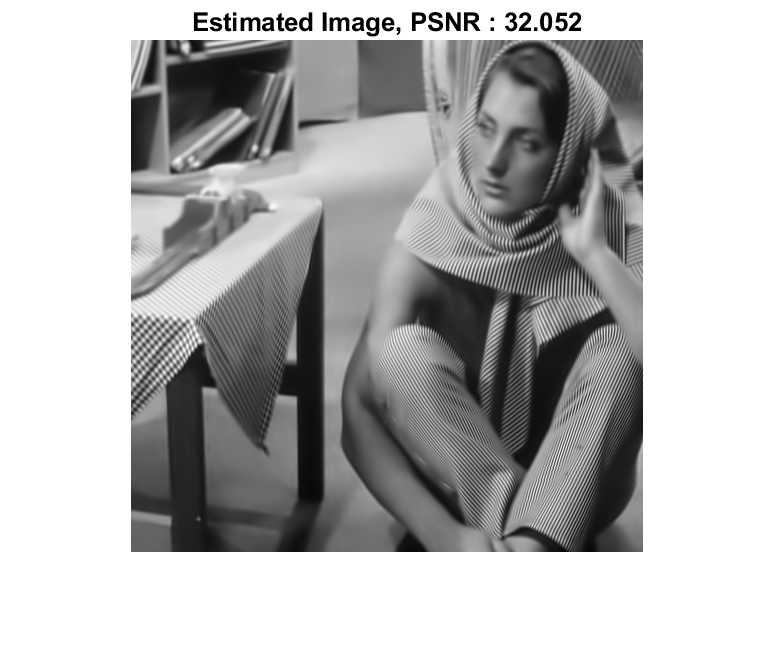

figure(), imshow(img_hat,[]), title(['Estimated Image, ', str])